1.首先导入数据

2. 通过fft，单边频谱查询AC部分最佳period，从而确定窗口（FIR）；阻带频率，通带频率，以及过渡带宽，波纹，以及阶数（IIR）

3. 设计相应的滤波器，FIR：中值滤波器，平均滤波器；IIR：巴特沃斯滤波器，切比雪夫2阶滤波器

clear, clc, close all
data = csvread("PPG_9_calibration.csv",1);
fs = 100; % 100 samples per second
ts = 1/fs; % sample period  
% start_index = 4001;
% N = 3000; % N is the number of samples
% t = 0:ts:(N-1)*ts; % time axis
% Ir = (6.4/4096).*data(start_index:start_index+N-1,1); % change the magnitude to mA, IR
% Red = (6.4/4096).*data(start_index:start_index+N-1,2); % Red
Ir = (6.4/4096).*data(:,1);
Red = (6.4/4096).*data(:,2);
N = length(Ir);
t = 0:ts:(N-1)*ts; % time axis

画出raw data图像

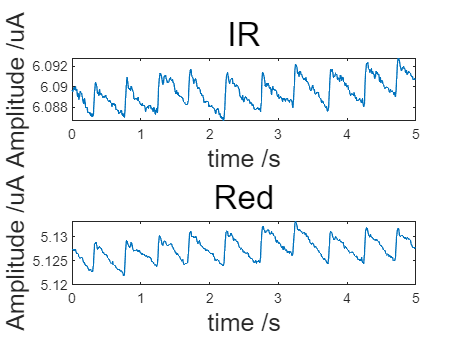

close all;
figure
subplot(2,1,1);
plot(t, Ir);
subtitle("IR", "FontSize", 20)
xlabel("time /s", "FontSize", 15)
ylabel("Amplitude /uA", "FontSize", 15)
subplot(2,1,2);
plot(t, Red);
subtitle("Red","FontSize", 20)
xlabel("time /s", "FontSize", 15)
ylabel("Amplitude /uA", "FontSize", 15)

快速傅里叶，看单边频谱的特征

在**Matlab中，进行FFT变换后需要除以n**，因为FFT变换时会将离散信号展开为周期信号，而周期信号的能量会在多个离散点上重复出现，因此需要将FFT变换后得到的所有点的值除以信号长度n，以获得单个离散点的能量。

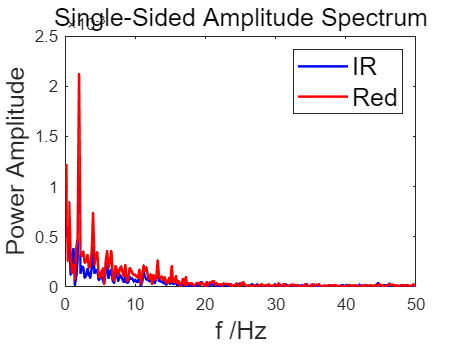

Y = fft(Ir);
P2 = abs(Y/N); % must divide by n to obtain the single energ
f = (fs/N)*(1:floor(N/2)); % single side specturm, delete f=0, as this point is meaning less
P1 = 2*P2(2:floor(N/2)+1); % as it's single side specturm, the energy will double except f = 0

Y2 = fft(Red);
P2_2 = abs(Y2/N);
P1_2 = 2*P2_2(2:floor(N/2)+1);

close all;
figure
plot(f,P1, "b", f, P1_2, "r", "LineWidth", 1.5)
title('Single-Sided Amplitude Spectrum', "FontSize", 15)
legend(["IR", "Red"], "FontSize", 15)
xlabel('f /Hz', 'FontSize', 15)
ylabel('Power Amplitude', "FontSize", 15)

We assume that beat-to-beat interval is 0.5s as the heart-beat is assume to be ~2Hz.

i) Mildly smoothed waveform w1. We first smoothed the  waveform w0 using a center median filter, with a window size set to **one-tenth of the estimated beat-to-beat interval** (i,e, 0.05s, 5 samples),  followed by a center moving-average filter with the same  window size. (The median filter was a robust filter but might  introduce edge jitters. The moving-average filter reduced  such edge jitters and enhanced the smoothness of the  waveform signal.) The two filters removed noise and sharp  spikes whose frequencies were more than ten times that of  the estimated heart-beat frequency (cutoff frequency will be 20Hz). Fig. 1(c) illustrates that  the smoothed waveform, denoted as w1, is smoother than w0 and has slightly lower amplitude at the peak positions. 

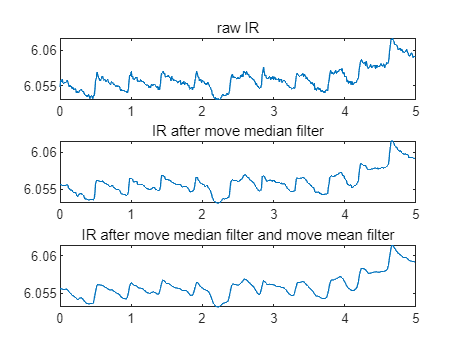

beat_to_beat_interval = 1/2; % define heart rate = 0.5s
window_size = 0.1*beat_to_beat_interval*fs ; % one-tenth of samples rating, i,e 100/20 = 5
movemedian_data = smoothdata(Ir,"movmedian",window_size);
movemean_data = smoothdata(movemedian_data,"movmean", window_size);

figure
subplot(3,1,1);
plot(t,Ir);
subtitle("raw IR");
subplot(3,1,2);
plot(t,movemedian_data);
subtitle("IR after move median filter");
subplot(3,1,3);
plot(t,movemean_data); % the movemean take movemedian as input
subtitle("IR after move median filter and move mean filter");

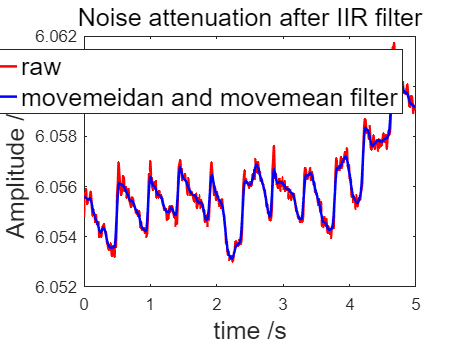


figure
plot(t,Ir,'r-',t,movemean_data,'b-',"LineWidth", 1.5)
legend(["raw","movemeidan and movemean filter"],"FontSize",15)
xlabel("time /s", "FontSize", 15)
ylabel("Amplitude /uA", "FontSize", 15);
title("Noise attenuation after IIR filter","FontSize",15)

ii) Filtered waveform w2. **The smoothed waveform w1 was passed through a third-order, low-pass Butterworth filter with a cutoff frequency of one-and-a-half times the estimated heart-beat frequency (1.5*2 = 3Hz)(we directly smooth raw siganl IR) .** This filter removed ectopic peaks  whose frequencies were higher than 1.5 the estimated  heart-beat frequency. This filtered waveform is denoted as w2.  Fig. 1(c) illustrates that two potential peaks on w1 between  517 and 518 s are filtered out, resulting in only one peak on w2  in this time interval.

close all;
% This is a lowpass filter design for buttord filter
fp = 1.5/beat_to_beat_interval; % pass frequency is 3 Hz
fc = 5/beat_to_beat_interval; % stop frequecny is 10 Hz
rp = 0.1; % passband ripple at most 0.1 dB, this can be fixed
rs = 10; % stopband ripple at least 10 dB, this can be fixed
wp = fp/(fs/2); % passband width is 3 Hz, fs divided by 2 because of Nyquist's criterion
ws = fc/(fs/2); % stopband width is 15 Hz, i,e transmission band will be 3 to 15Hz
[n,Wn] = buttord(wp, ws, rp, rs) % design the buttord parameters

n = 3

Wn = 0.1411

[b,a] = butter(n,Wn,'low') % return the parameters for design IIR

b =     0.0073    0.0219    0.0219    0.0073


a =     1.0000   -2.1201    1.5876   -0.4090


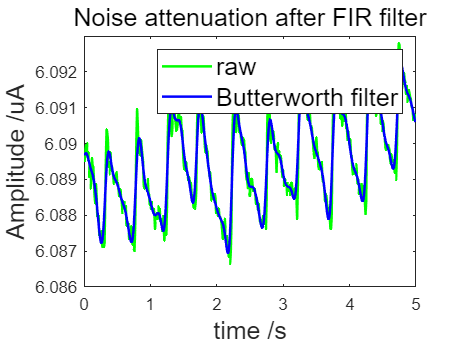

freqz(b,a,[],fs)
subplot(2,1,1)

% 
% [n,wn]=buttord(wp,ws,rp,rs,'s') %'s 是确定巴特沃斯模拟滤波器阶次和3dB
% [z,P,k]=buttap(n); %设计归一化巴特沃斯模拟低通滤波器，z为极点，p为零点和k为增益
% [bp,ap]=zp2tf(z,P,k); %转换为Ha,bp为分子系数，ap为分母系数
% [bs,as]=lp2lp(bp,ap,wp); %Ha转换为低通Ha(s)并去归一化，bs为分子系数，as为分母系数
% [bz,az]=bilinear(bs,as,fs); %对模拟滤波器双线性变换
% m=filter(bz,az,Ir);
% figure
% freqz(bz,az);title('巴特沃斯低通滤波器幅频曲线')


% butter_data=filter(b,a,Ir);
% now we use filtfilt zero-phase response to filter the data
butter_data=filtfilt(b,a,Ir);

% [n,Wn] = cheb2ord(wp,ws,rp,rs)
% [b,a] = cheby2(n,rs,Wn); % cheby2(n,Rs,Wn,options), cheby1(n,Rp,Wn,options)
% cheby2_data = filter(b,a,Ir);
% figure(1)
% freqz(b,a,[],fs)

close all;
figure(2)
% subplot(2,1,1);
% plot(t,Ir);
% subtitle("raw IR");
% subplot(2,1,2);
% plot(t, butter_data);
% subtitle("IR after butterword");
plot(t,Ir,'g-',t,butter_data,'b-',"LineWidth", 1.5)
legend(["raw","Butterworth filter"], "FontSize", 15)
xlabel("time /s", "FontSize", 15)
ylabel("Amplitude /uA", "FontSize", 15)
title("Noise attenuation after FIR filter", "FontSize", 15)

它们与滤波器设计函数结合使用时非常有用。假设您需要一个具有以下设定的带通滤波器：通带为 1000 至 2000 Hz，阻带从通带两侧外 500 Hz 处开始，采样频率为 10 kHz，通带波纹至多 1 dB，阻带衰减至少 60 dB。您可以通过使用以下 `butter` 函数来满足这些设定。

`[n,Wn] = buttord([1000 2000]/5000,[500 2500]/5000,1,60)`

`[b,a] = butter(n,Wn);`

wp: 带通为0.5Hz到15Hz

ws: 带阻从带通两侧左右0.1Hz开始, 到40Hz截止

rp: 带通波纹最多1dB

rs: 阻带波纹最少60dB

n: order 阶数

wn: window size窗口

fs = 100;

wp = [0.5 15]/(fs/2);

ws = [0.1 40]/(fs/2);

rp = 1;

rs = 60;

ans: n=5, wn = 0.0078, 0.376; 注意这是个带通滤波器！！！

iii) Baseline b. **We estimated a baseline b of the PPG  waveform by applying a center moving-average filter to  waveform w2 (we smooth raw siganl IR directly), with a window size set to 1.5 of the estimated  beat-to-beat interval (we assume beat-to-beat frequency is 2 HZ, or 0.5 second, so 1.5 * 0.5 = 0.75 seconds, 1.5*fs = 75 samples). **This selection attempted to optimize the detection of PPG peaks at the heart-beat frequency [7] as  discussed below in the onset and peak detection stages. Fig.  1(c) shows that baseline b is smoother than the filtered  waveform w2 and reflects the baseline fluctuation of the PPG  waveform. 

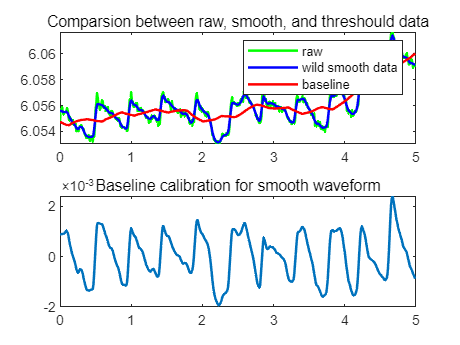

window_size_2 = 1.5*beat_to_beat_interval*fs; % hr = 0.5; fs = 100 samples/sec, hr*fs = 50 samples/beat-to-beat
movemean_data_baseline = smoothdata(Ir,"movmean", window_size_2);
eliminate_baseline_data = movemean_data - movemean_data_baseline;

close all
figure
subplot(2,1,1)
plot(t,Ir,'g-',t,movemean_data,'b-',t,movemean_data_baseline,'r-', "LineWidth", 1.5)
legend("raw","wild smooth data","baseline")
title("Comparsion between raw, smooth, and threshould data")
subplot(2,1,2)
plot(t,eliminate_baseline_data, "LineWidth", 1.5)
title("Baseline calibration for smooth waveform")

现在直接用butterworth带通滤波器实现，噪音和基线去除。

close all;
wp = [2 5]/(fs/2);
ws = [1 10]/(fs/2);
rp = 0.1;
rs = 10;
[n,Wn] = buttord(wp, ws, rp, rs) % design the buttord parameters

n = 3

Wn =     0.0265    0.1497


[b,a] = butter(n,Wn,'bandpass') % return the parameters for design IIR

b =     0.0051         0   -0.0153         0    0.0153         0   -0.0051


a =     1.0000   -5.1266   11.0595  -12.8649    8.5171   -3.0437    0.4586


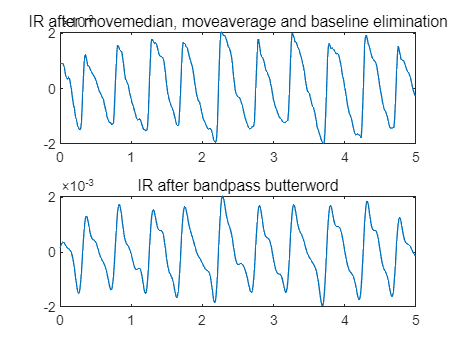

figure
freqz(b,a,[],fs)
subplot(2,1,1)

bandpass_butter_data=filtfilt(b,a,Ir);

close all;
figure(2)
subplot(2,1,1);
plot(t,eliminate_baseline_data);
subtitle("IR after movemedian, moveaverage and baseline elimination");
subplot(2,1,2);
plot(t,bandpass_butter_data);
subtitle("IR after bandpass butterword");

close all;
% This is a lowpass filter design for buttord filter
fp = 0.5/beat_to_beat_interval; 
fc = 1/beat_to_beat_interval; 
rp = 0.1; % passband ripple at most 0.1 dB, this can be fixed
rs = 10; % stopband ripple at least 10 dB, this can be fixed
wp = fp/(fs/2); % passband width is 3 Hz, fs divided by 2 because of Nyquist's criterion
ws = fc/(fs/2); % stopband width is 15 Hz, i,e transmission band will be 3 to 15Hz
[n,Wn] = buttord(wp, ws, rp, rs) % design the buttord parameters

n = 5

Wn = 0.0321

[b,a] = butter(n,Wn,'low') % return the parameters for design IIR

b = 	1.0e+-5 *

    0.0279    0.1395    0.2791    0.2791    0.1395    0.0279


a =     1.0000   -4.6734    8.7465   -8.1936    3.8418   -0.7213


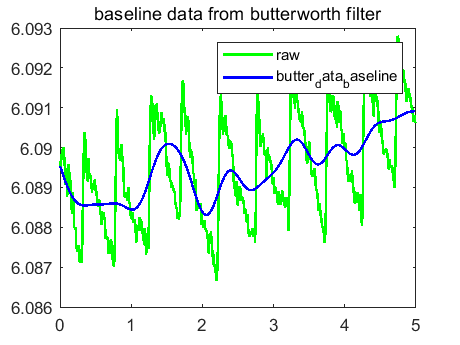

freqz(b,a,[],fs)
subplot(2,1,1)
butter_data_baseline=filtfilt(b,a,Ir);

close all;
figure(1)
plot(t,Ir,'g-',t,butter_data_baseline,'b-',"LineWidth", 1.5)
legend("raw","butter_data_baseline")
title("baseline data from butterworth filter")

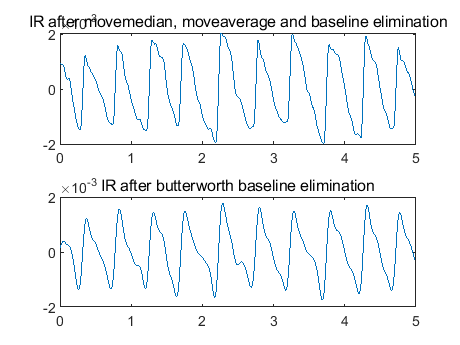


eliminiate_baseline_data_butter = butter_data - butter_data_baseline;
figure(2)
subplot(2,1,1);
plot(t,eliminate_baseline_data);
subtitle("IR after movemedian, moveaverage and baseline elimination");
subplot(2,1,2);
plot(t,eliminiate_baseline_data_butter);
subtitle("IR after butterworth baseline elimination");

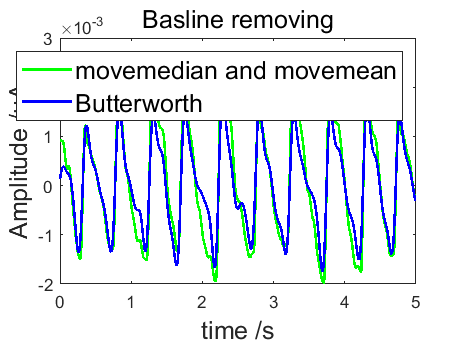


figure(3)
plot(t,eliminate_baseline_data,"g-",t,eliminiate_baseline_data_butter,"b-","LineWidth",1.5)
legend(["movemedian and movemean","Butterworth"], "FontSize",15)
xlabel("time /s", "FontSize", 15)
ylabel("Amplitude /uA", "FontSize", 15)
title("Basline removing", "FontSize", 15)

**Peak identification.** 

### 大类型1：局部最值法

We identified PPG peaks in  three steps: (i) the identification of initial peaks, where we  selected a set of initial peaks; (ii) the detection of potential  false peaks, where we assessed the validity of each initial  peak by analyzing the height of each peak and the  peak-to-peak interval (to its preceding peak); and (iii) the  relocation of potential missed peaks.

i) **Identification of initial peaks.** We identified an initial  set of peaks on w0 by finding a local maximum in each **time  interval where the filtered waveform w2 is above the baseline  b** .

直接用w2（巴特沃斯滤波器后的信号）确定w0局部最值的范围。

ii) **Detection of potential false peaks.** We detected  potential false peaks from the initial set by imposing certain  requirements on the peak’s height and peak-to-peak interval.  **First,** we sorted all peaks on w0 by height in increasing order  and selected the height value at the 2/3 length position. Next,  we required that **each initial peak had a height greater than  half of the selected height value. Then**, we computed the  **median absolute deviation (MAD) of the peak-to-peak intervals t, with MAD = median[|t-median(t)|],** and** required  that each interval not deviate from the median interval by  more than two times MAD. **We marked the PPG peaks not  satisfying these two conditions as potential false peaks and  the remaining as true peaks [Fig. 1(d)]. 

第一个，判断峰值的绝对幅度是否大于某个值，比如这里的2/3quantile值。

第二个，判断两个峰值之间的时间间隔，时间间隔应该要不大于2倍的时间间隔的中值均差。

iii) **Relocation of missed peaks.** For intervals between  true PPG peaks on w0 where potential false peaks were  detected, we attempted to relocate putative false peaks and  identify the locations of true ones. **Specifically, starting from  the left-boundary position of each interval, we advanced  median(t) seconds and marked this point as the expected  position of the next peak. *****Next, we searched around the  expected position to identify a local maximum on the  smoothed waveform w1 within a window size of length set to  MAD*****. *****If the local maximum was located at either end of the  window, we increased the window size by MAD seconds and  repeated the process until the maximum was located inside  the window. ***Then, we identified the equivalent maximum on  w0 and labeled it as the next peak. Starting from this newly  discovered peak position, we repeated the procedure above  until we reached the end of the interval and by doing so  recovered multiple consecutive missed peaks. ***We did not  impose the peak height and peak-to-peak interval conditions  described in the previous step on these newly discovered  peaks and deemed them to be true peaks.*** Fig. 1(e) illustrates  that a missed peak was recovered at 515 s, a potential false  peak was confirmed to be a true peak between 515 and 516 s,  and a false peak was relocated to an earlier time with a lower  peak height between 518 and 519 s.

这个方法其实有点在弥补第二个detection of potential false  peaks的缺陷。再从MAD的均差时间t再去找局部最大值。找到以后也不再按照第二个方法那样去检测是不是错误的峰值（这会默认找到的就是真实的峰值）。

**Onset detection.** 

We identified the onset position  corresponding to each true peak in three steps. **First, we found  ranges where w0 was below both the filtered waveform w2 and the baseline b. **This was to ensure that the identified onsets  would be insensitive to different selections of baselines (here  we considered the filtered waveform w2 as another potential  baseline). **Second, if there were multiple ranges identified, we  ranked them based on their lengths, and selected the  rightmost one from the top two ranges. **This ensured that,  when multiple potential onsets existed, we would find the  major one closer to the left of the peak.** Finally, we identified  the minimum position on the waveform w0 in the selected  range as the onset location.** Fig. 1(f) illustrates the onsets  identified by the algorithm. 

也是局部最小值的招法，关键是局部范围的确定，他是用baseline和w2(巴特沃斯滤波器处理后的信号）去确定这个局部范围的。

另一篇文献的做法如下：

After the high-pass filter, the filtered PPG and the raw signal annotation of the PPG are stored in two ring buffers the size of two times the longest permitted duration of a pulse wave, particularly 4.8 s each. The fourth stage then detects potential valleys and peaks of a pulse wave.*** Therefore, an adaptive threshold is calculated by applying a moving average filter with a span size of 75% of the last valid PWD. ***The value 75% was chosen after a comparison analysis with 50% and 100% based on the development set in order to get a threshold, which better tracks dc changes than 100% without as many false detection of peak candidates in the presence of strong diastolic peaks as compared to 50%.** Then, the absolute maximum is identified as potential pulse wave peak in every part of the signal above this threshold, and the absolute minimum is selected as potential pulse wave valley in every signal part below.** This allows the detection of potential valleys and peaks even in signals with dc drift (see Fig. 4, mark A). Thereafter, wrongly detected potential peaks and corresponding valleys belonging to diastolic peaks are** discarded by demanding that the vertical distance between them multiplied by a factor must be bigger than the previous valid PWA (see Fig. 4, mark B).** Based on the development set, **the factor was set to 3. **The results of these detections are stored synchronously to the filtered PPG ring buffer in the PPG annotation ring buffer.

这篇文章用75%PWD的window size的平均滤波器的来确定局部最值的范围。

这里的PWD（pulse wave duration）我们默认和beat-to-beat的时间是一样的，都是0.5s，2Hz.

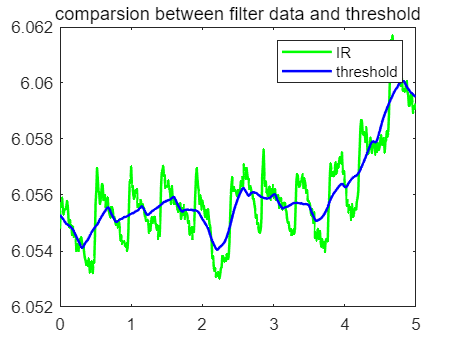

window_size_3 = floor(0.75*beat_to_beat_interval*fs); % 0.75*0.5*100 = 37.5
movemean_threshould = smoothdata(Ir,"movmean", window_size_3);

close all
figure
plot(t,Ir,'g',t,movemean_threshould,'b',"LineWidth", 1.5)
legend("IR","threshold")
title("comparsion between filter data and threshold")

先标记出那些peak和valley的点

接下来把分成peaks（和对应的时间）和vallies（和对应的时间）4个vectore提取出来。

% fixed vector with peak and vally notation
window_size = N; % window_size should smaller than buffer length N
max_min_index_arr = loc_min_max(movemean_data, movemean_threshould, window_size);
% the number of maxs and mins
max_nb = number_max(max_min_index_arr,window_size);
min_nb = number_min(max_min_index_arr,window_size);
% the vectors for time and value of maxs and mins
t_max = maximums(max_nb,max_min_index_arr,t);
maxs = maximums(max_nb,max_min_index_arr,movemean_data);
t_min = minimums(min_nb,max_min_index_arr,t);
mins = minimums(min_nb,max_min_index_arr,movemean_data);

接下来画出这些特征点和对应去除噪音的点的图

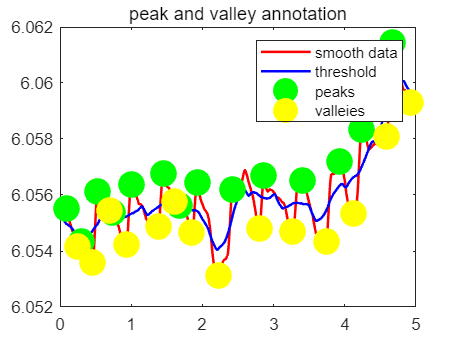

close all
figure
plot(t,movemean_data,'r',t,movemean_threshould,'b',"LineWidth", 1.5);
hold on
plot(t_max,maxs,"go",t_min,mins,"yo","LineWidth",10);
legend("smooth data","threshold","peaks","valleies");
title("peak and valley annotation")

% figure

接下来是检测可能的错误的峰值和谷值

先找valley，右边最近的peak就是raise time, 并且这两个值之间就是PWA。

如果离这个valley最近的点不是peak而是valley，那说明这个值也是不对的，需要标记出来

如果算出来的PWA的值乘以系数3后仍然小于前一个PWA的幅值，则说明这是一个fake notation

再标记出这些值之后就进行PWD的计算（PWD=second valley time - first valley time）

对于某一段区间来讲，min_nb和max_nb并不一定相等

% max_nb, min_nb, t_max, t_min, maxs, mins
peak_check = zeros(1,max_nb);
valley_check = zeros(1,min_nb);

% check whether there are two continuous peaks or valleys
for i = 1:min_nb 
    next_valley_index = valley_next_peak(t_min,min_nb,i,t_min(i));
    next_peak_index = valley_next_peak(t_max,max_nb,i,t_min(i));
    if (next_valley_index ~= -1 && next_peak_index ~= -1)
        if (t_min(next_valley_index) < t_max(next_peak_index)) 
            valley_check(i) = -1; % continuous valley error
        end
    end
end
for i = 1:max_nb 
    next_peak_index = valley_next_peak(t_max,max_nb,i,t_max(i));
    next_valley_index = valley_next_peak(t_min,min_nb,i,t_max(i));
    if (next_peak_index ~= -1 && next_valley_index ~= -1) 
        if (t_max(next_peak_index) < t_min(next_valley_index)) 
            peak_check(i) = -1; % continuous peak error
        end
    end
end

% check Pulse Wave Amplutide
factor = 3;
pervious_PWA = 0;
PWA = 0;
for i = 1:min_nb 
%     if (valley_check(i) == -1) % continous errror has been marked
%         continue;
%     end
    pervious_PWA = PWA;
    next_peak_index = valley_next_peak(t_max,max_nb,i,t_min(i));
    if (next_peak_index ~= -1) 
        PWA = maxs(next_peak_index)-mins(i);
        if (i == 1) % the initial PWA is ommited
            continue; 
        end
        if (PWA*factor < pervious_PWA) 
            peak_check(next_peak_index) = 1; % annotation false peak and valley
            valley_check(i) = 1;
        end
    end
end

现在数据可视化

1. 标出错误的连续的峰值或者谷值

2. 标出错误的PWA峰值和谷值

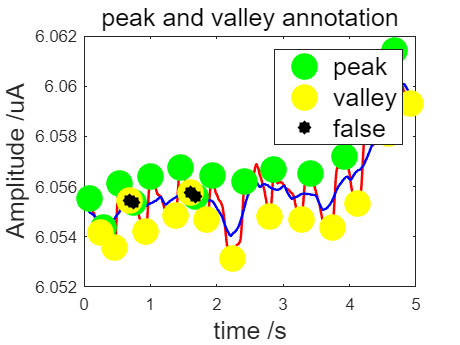

% find the number of continous valley and peak
continous_valley_nb = number_min(valley_check,min_nb); % -1 is for continuous mark
continous_peak_nb = number_min(peak_check,max_nb);
% find the time and value of continuous valley and peak
t_continous_valley = minimums(continous_valley_nb,valley_check,t_min);
continous_valley = minimums(continous_valley_nb,valley_check,mins);
t_continous_peak = minimums(continous_peak_nb,peak_check,t_max);
continous_peak = minimums(continous_peak_nb,peak_check,maxs);

% find the PWA false valley
PWA_valley_nb = number_max(valley_check,min_nb);
PWA_peak_nb = number_max(peak_check,max_nb);
% find the time and value of PWA false valley and peak
t_PWA_valley = maximums(PWA_valley_nb,valley_check,t_min);
PWA_valley = maximums(PWA_valley_nb,valley_check,mins);
t_PWA_peak = maximums(PWA_peak_nb,peak_check,t_max);
PWA_peak = maximums(PWA_peak_nb,peak_check,maxs);

% plot out
figure
plot(t,movemean_data,'r',t,movemean_threshould,'b',"LineWidth", 1.5);
hold on
plot(t_max,maxs,"go",t_min,mins,"yo","LineWidth",10);
hold on
if (continous_valley_nb > 0) 
    plot(t_continous_valley,continous_valley,"c*","LineWidth",6);
    hold on
%     legend("","","peaks","valleies","continous fake valley");
end
if (continous_peak_nb > 0) 
    plot(t_continous_peak,continous_peak,"c*","LineWidth",6);
    hold on
%     legend("","","peaks","valleies","continous fake peak");
end
if (PWA_valley_nb > 0) 
    plot(t_PWA_valley,PWA_valley,"k*","LineWidth",6);
    hold on
%     legend("","","peaks","valleies","PWA fake valley");
end
if (PWA_peak_nb > 0) 
    plot(t_PWA_peak,PWA_peak,"k*","LineWidth",6);
    hold on
%     legend("","","peaks","valleies","PWA fake peak");
end
xlabel("time /s", "FontSize", 15)
ylabel("Amplitude /uA", "FontSize", 15)
legend(["","","peak", "valley","false"],"FontSize",15)
title("peak and valley annotation", "FontSize",15)

Each time a complete pulse wave (called N-1 pulse wave) is recorded, the fifth stage with the second decision list checks absolute and relative pulse wave characteristics. Based on literature-reported values, the permitted range for rise time was set from 0.08 to 0.49 s, for systolic-to-diastolic duration ratio (S/D) up to 1.1, for PWD from 0.27 to 2.4 s which corresponds to a pulse rate from 220 to 25 beats/min, and for the number of diastolic peaks up to 2. The remaining checks in the second decision list are intended to prevent pulse wave detection in a pure noise signal (Check 3) or to detect disturbances of the overall PWF (Check 8 to 10). This artifact annotation is also stored synchronously to the filtered PPG ring buffer in the PPG annotation ring buffer.

计算PWA，PWD，Systolic Phase (rising time), Diastolic Phase

% PWD 计算
t_previous_valley = 0;
PWD_list = zeros(1,min_nb);
PWD_false_nb = 0;
flag = true;
for i = 1:min_nb
    if (valley_check(i) ~= 0)
        flag = true;
        PWD_false_nb = PWD_false_nb + 1;
    end
    if (valley_check(i) == 0 && flag == true) 
        t_previous_valley = t_min(i);
        flag = false;
    end
    if (valley_check(i) == 0 && flag == false)
        PWD = t_min(i) - t_previous_valley;
        PWD_list(i) = PWD;
        t_previous_valley = t_min(i);
    end
end
PWD_list

PWD_list =          0    0.2700    0.4500    0.2600    0.1500    0.4800         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.4900    0.5100         0         0         0         0    0.4800    0.5400    0.4800    0.5200    0.4700    0.4600    0.4900    0.4700         0         0    0.4500    0.4400    0.4100    0.4200         0         0    0.2500


PWD_nb = (min_nb - 1) - PWD_false_nb

PWD_nb = 51

% this windows overall over signal behaivor
overall_average_PWD = sum(PWD_list)/PWD_nb

overall_average_PWD = 0.3494

% Systolic Phase (rising time)计算
systolic_phase = zeros(1,min_nb);
systolic_nb = 0;
for i = 1:min_nb 
    if (valley_check(i) == 0)
        next_peak_index = valley_next_peak(t_max,max_nb,i,t_min(i));
        if (next_peak_index ~= -1) % avoid the last index is -1;
            if (peak_check(next_peak_index) == 0) % both valley and peak are valid
                rising_time = t_max(next_peak_index) - t_min(i);
                systolic_phase(i) = rising_time;
                systolic_nb = systolic_nb + 1;
            end
        end
    end
end
systolic_phase

systolic_phase =     0.1700    0.2600    0.1200    0.0700    0.2200    0.0900         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3400    0.1100    0.0700         0    0.0900         0    0.1200    0.1200    0.0600    0.0800    0.0800    0.0700    0.0600    0.1400    0.0800         0    0.0700    0.0600    0.0700    0.0600    0.0600         0    0.1000    0.1100


systolic_nb

systolic_nb = 47

% this windows overall over signal behaivor
overall_systolic_phase = sum(systolic_phase)/systolic_nb

overall_systolic_phase = 0.1009

% Diastolic Phase 计算
diastolic_phase = zeros(1,max_nb);
diastolic_nb = 0;
for i = 1:max_nb 
    if (peak_check(i) == 0)
        next_valley_index = valley_next_peak(t_min,min_nb,i,t_max(i));
        if (next_valley_index ~= -1) % avoid the last index is -1;
            if (valley_check(next_valley_index) == 0) % both valley and peak are valid
                down_time = t_min(next_valley_index) - t_max(i);
                diastolic_phase(i) = down_time;
                diastolic_nb = diastolic_nb + 1;
            end
        end
    end
end
diastolic_phase

diastolic_phase =     0.1000    0.1900    0.1400    0.0800    0.2600         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.2500         0    0.1500    0.4000         0         0         0         0    0.3600    0.4200    0.4200    0.4400    0.3900    0.3900    0.4300    0.3300         0         0    0.3800    0.3800    0.3400    0.3600         0         0    0.1500    0.1200


diastolic_nb

diastolic_nb = 43

% this windows overall over signal behaivor
overall_diastolic_phase = sum(diastolic_phase)/diastolic_nb

overall_diastolic_phase = 0.3219

% PWA计算
PWA_list = zeros(1,min_nb);
valiad_PWA_nb = 0;
for i = 1:min_nb 
    if (valley_check(i) == 0)
        next_peak_index = valley_next_peak(t_max,max_nb,i,t_min(i));
        if (next_peak_index ~= -1) % avoid the last index is -1;
            if (peak_check(next_peak_index) == 0) % both valley and peak are valid
                PWA = maxs(next_peak_index) - mins(i);
                PWA_list(i) = PWA;
                valiad_PWA_nb = valiad_PWA_nb + 1;
            end
        end
    end
end
PWA_list

PWA_list =     0.0003    0.0016    0.0016    0.0006    0.0016    0.0018         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0014    0.0028    0.0017         0    0.0021         0    0.0021    0.0021    0.0019    0.0018    0.0027    0.0017    0.0015    0.0032    0.0024         0    0.0019    0.0017    0.0022    0.0017    0.0021         0    0.0021    0.0008


valiad_PWA_nb

valiad_PWA_nb = 47

% this windows overall over signal behaivor
overall_PWA = sum(PWA_list)/valiad_PWA_nb

overall_PWA = 0.0022